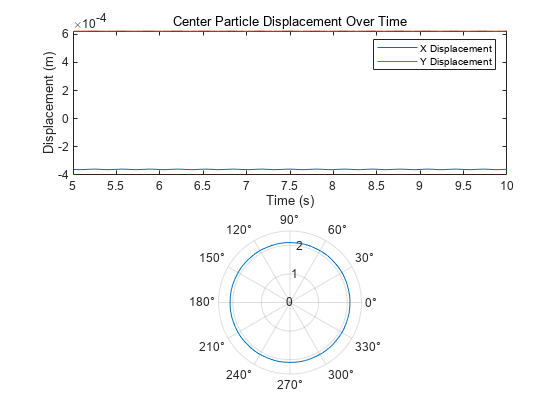

tz=10;
dt=0.01;
j2=tz./dt;
b=0;%阻尼
Z=1000;%电荷
a=1.8*10^(-4);%间距
T=300;
D=(T.*a.^3./Z.*4.770703125.*10.^3).^(0.5);
k=1./D;
tesx1=zeros(1,j2);
tesy1=zeros(1,j2);
% 将中心粒子的初始扰动设置为朝右偏上60°
%theta = pi/3; % 60度
%initial_displacement = 0.05; % 初始扰动幅度
%x(51, 51) = x(51, 51) + initial_displacement * cos(theta);
%y(51, 51) = y(51, 51) + initial_displacement * sin(theta);
tx=zeros(101,101);
ty=zeros(101,101);
s=0;
x=zeros(101,101);
y=zeros(101,101);
for i=1:1:101
    if (mod(i,2)==0)
        for j=2:2:100
            x(i,j)=0.5*a*(j-51);
            y(i,j)=0.5*sqrt(3)*a*(51-i);
        end
    else
        for j=1:2:101
            x(i,j)=0.5*a*(j-51);
            y(i,j)=0.5*sqrt(3)*a*(51-i);
        end
    end
end
q=Z.*1.6*10^(-19)*ones(101,101);
vx=zeros(101,101);
vy=zeros(101,101);
m=6.13*10^(-13)*ones(101,101);
xc=x;
yc=y;
f=3.125;%频率
for t=0:dt:tz
    x(51,51)=0.05.*a.*sin(2.*3.1415926.*f.*t);
    xt=x;yt=y;vxt=vx;vyt=vy;
    for i=2:1:100
        if (mod(i,2)==0)
            for j=4:2:98
                [x(i,j),y(i,j),vx(i,j),vy(i,j)]=xlg(xt(i,j),yt(i,j),vxt(i,j),vyt(i,j),dt,xt(i,j-2),xt(i+1,j-1),xt(i-1,j-1),xt(i-1,j+1),xt(i+1,j+1),xt(i,j+2),yt(i,j-2),yt(i+1,j-1),yt(i-1,j-1),yt(i-1,j+1),yt(i+1,j+1),yt(i,j+2),q(i,j),q(i,j-2),q(i+1,j-1),q(i-1,j-1),q(i-1,j+1),q(i+1,j+1),q(i,j+2),k,m(i,j),b);
            end
        else
            for j=3:2:99
                [x(i,j),y(i,j),vx(i,j),vy(i,j)]=xlg(xt(i,j),yt(i,j),vxt(i,j),vyt(i,j),dt,xt(i,j-2),xt(i+1,j-1),xt(i-1,j-1),xt(i-1,j+1),xt(i+1,j+1),xt(i,j+2),yt(i,j-2),yt(i+1,j-1),yt(i-1,j-1),yt(i-1,j+1),yt(i+1,j+1),yt(i,j+2),q(i,j),q(i,j-2),q(i+1,j-1),q(i-1,j-1),q(i-1,j+1),q(i+1,j+1),q(i,j+2),k,m(i,j),b);
            end
        end
    end
    tc=5;%t的初始值
    if t>tc
        s=s+1;
        tesx1(s)=x(47,47);
        tesy1(s)=y(47,47);
    else
        tesx1(1)=[];
        tesy1(1)=[];
    end
end 

%分析偏振特性
time = tc+dt:dt:tz;
figure;
subplot(2, 1, 1);
plot(time, tesx1, time, tesy1);
title('Center Particle Displacement Over Time');
xlabel('Time (s)');
ylabel('Displacement (m)');
legend('X Displacement', 'Y Displacement');

% 绘制中心粒子的轨迹
subplot(2,1,2);
plot(tesx1, tesy1);
title('Center Particle Trajectory');
xlabel('X Displacement (m)');
ylabel('Y Displacement (m)');
axis equal;

% 计算偏振特性
theta = atan2(tesy1, tesx1); % 计算每个时间步长的偏振角
polarplot(theta); % 绘制偏振图

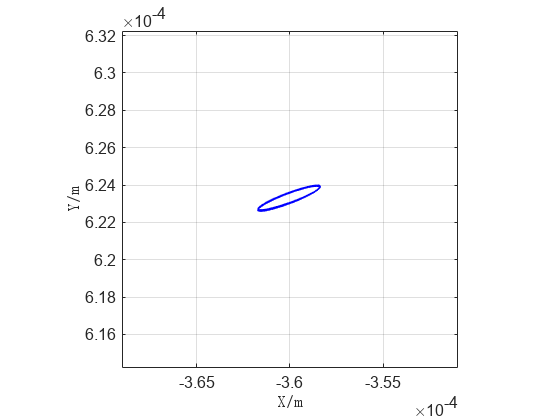

% 绘制李萨如图
figure;
plot(tesx1, tesy1,'LineWidth',1,'Color','b');
set(gca,'FontSize',12)
xlabel('X/m','FontSize',12,'FontName','Arial Unicode MS');
ylabel('Y/m','FontSize',12,'FontName','Arial Unicode MS');
set_axis_length('x', 1.8*10^(-5)) 
set_axis_length('y', 1.8*10^(-5)) 
title('Lissajous Figure of Particle Motion','FontSize',10,'FontName','Arial Unicode MS');
axis square
%axis off;  % 隐藏坐标轴
grid on;  % 网格线
% 隐藏坐标轴上的度量值
%set(gca, 'XTick', [], 'YTick', []);

% 隐藏坐标轴的名称
%xlabel('');
%ylabel('');

% 隐藏图表的标题
title('');


%保存图像到指定路径
%指定文件夹和文件名
%foldera = 'E:\2024\data figure\data figure x tc-5\square fig line_L(jpg)';%替换为你要保存的路径
%filenamea = '47,55.jpg';% 文件名及格式

%将完整路径与文件名结合
%fullpath = fullfile(foldera, filenamea);

%保存图像并指定分辨率为 600 DPI
%exportgraphics(gcf, fullpath, 'Resolution', 600);